## Tarea 4

## Alejandro Brenes Calderón - C21319

## Santiago Fernández Sáenz - C22943

**1. **Considere el Algoritmo 1 para obtener la forma de Hessenberg $$H$$ de una matriz $$A$$ dada.

**a)**

Se realiza la función para obtener la matriz de Hessenberg correnpondiente.

function H = Hessenberg(A)
% Se define la matriz inicial
H = A;

% Dimensión de la matriz
m = size(A, 1);

% Ciclo para convertir iterativamente la matriz
for k = 1:(m - 2)
    % Vector columna de H
    x = H(((k + 1):m), k);

    % Vector canónico
    e = zeros(size(x, 1), 1);
    e(1) = 1;

    % Vector vk
    vk = sign(x(1)) .* norm(x, 2) .* e + x;

    % Se normaliza el vector vk
    vk = (vk / norm(vk, 2));

    % Modificación de la matriz H
    H(((k + 1):m), (k:m)) = H(((k + 1):m), (k:m)) - 2 .* vk .* (vk' * H(((k + 1):m), (k:m)));
    H((1:m), ((k + 1):m)) = H((1:m), ((k + 1):m)) - 2 .* (H((1:m), ((k + 1):m)) * vk) .* vk';
end
end

**b)**

Procedemos con el algoritmo pedido.

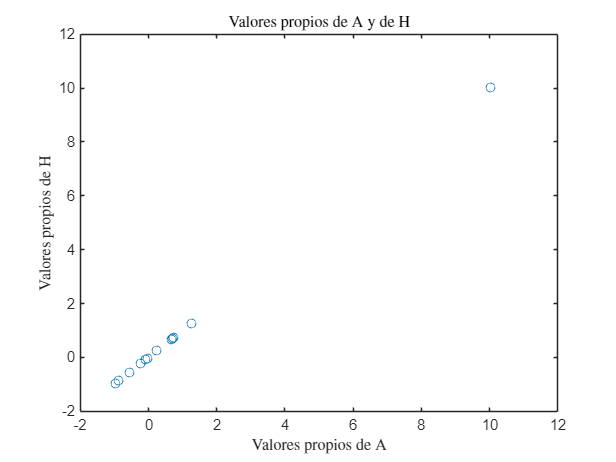

format long

% Matriz A
A = rand(20, 20);

% Se usa el algoritmo para obtener la forma de Hessenberg
H = Hessenberg(A);

% Valores propios
vp_A = eig(A);
vp_H = eig(H);

% Se muestra el gráfico correspondiente
figure;
plot(real(vp_A), real(vp_H), 'o')
title('Valores propios de A y de H', 'Interpreter', 'latex')
xlabel('Valores propios de A', 'Interpreter', 'latex');
ylabel('Valores propios de H', 'Interpreter', 'latex');


% Diferencia de los valores propios
error = norm(abs(vp_H - vp_A), 2);
fprintf('El error de los valores propios: %.16f\n', error);

El error de los valores propios: 0.0000000000000111
